clc; clear; close all;

## KITTI数据集可视化

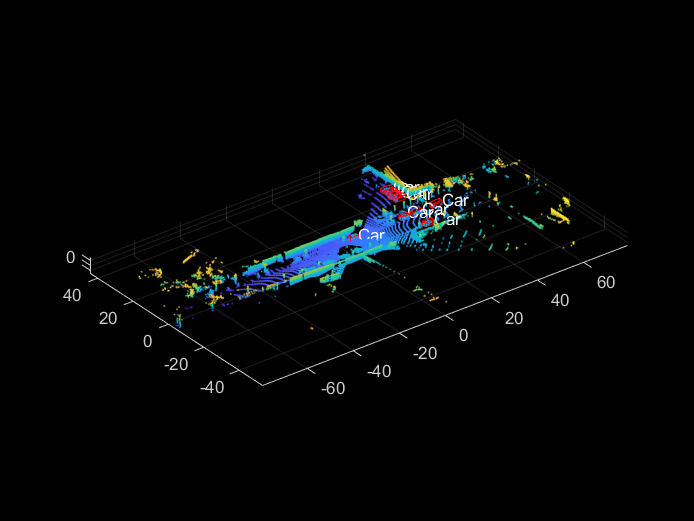

file = '003224';   % 文件编号 000099 117 19 49 5157 424 5157
fid=fopen(['./training/velodyne/',file,'.bin'],'rb');
[a,count]=fread(fid,'float32');
fclose(fid);
x = a(1:4:end);
y = a(2:4:end);
z = a(3:4:end);
reflectivity = a(4:4:end);
point_cloud = [x,y,z,reflectivity];
data = pointCloud([x y z]);
figure(1);
pcshow(data);hold on;

label = importdata(['./training/label/',file,'.txt']);
obsName = label.textdata;
data_label = label.data;
obsNum = size(data_label,1); % 包含DontCare类障碍物的总个数
obsCount = 0; % 初始化不包含DontCare类障碍物个数为0

data_calib = importdata(['./training/calib/',file,'.txt']);
Tr_velo_to_cam = reshape(data_calib.data(end-1,:),[4,3])';
Tr_velo_to_cam = [Tr_velo_to_cam;0 0 0 1];

pos = {};  % 创建一个cell数组用于存储障碍物坐标
for i = 1:obsNum
    if obsName{i} == "DontCare"
        continue;
    end
    obsCount = obsCount + 1;
    la = data_label(i,:);
    obsPos = la(11:13)';
    [h,w,l] = deal(la(8),la(9),la(10));
    r_y = la(end);
    
    % obsPos_velo = Tr_cam_to_velo*[obsPos;1];
    % obsPos_velo = obsPos_velo(1:3)
    % t1~t8为障碍物坐标系下的坐标（不考虑障碍物旋转，默认长边与x-axis平行）
    t1 = [l/2,0,w/2];
    t2 = [l/2,0,-w/2];
    t3 = [l/2,-h,w/2];
    t4 = [l/2,-h,-w/2];
    t5 = [-l/2,0,w/2];
    t6 = [-l/2,0,-w/2];
    t7 = [-l/2,-h,w/2];
    t8 = [-l/2,-h,-w/2];
    % 考虑障碍物旋转角度r_y，对x,z方向进行更新
    T = [t1;t2;t3;t4;t5;t6;t7;t8];
    R = [cos(r_y),-sin(r_y);sin(r_y),cos(r_y)];
    T(:,[1,3]) = (R*T(:,[1,3])')';
    % 考虑障碍物坐标系与相机坐标系坐标位移
    T(:,1) = T(:,1) + obsPos(1);
    T(:,2) = T(:,2) + obsPos(2);
    T(:,3) = T(:,3) + obsPos(3);
    % 将相机坐标系转化到激光雷达坐标系
    velo_pos = Tr_velo_to_cam\[T';1,1,1,1,1,1,1,1];
    velo_pos = velo_pos(1:3,:);
    % 记录障碍Box坐标
    pos{i} = velo_pos;
    % 绘制12根线构成3D-Box
    temp = [velo_pos(:,3),velo_pos(:,4),velo_pos(:,7),velo_pos(:,8)];
    [~,j] = max([velo_pos(1,3),velo_pos(1,4),velo_pos(1,7),velo_pos(1,8)]);
    textPoint = temp(:,j);
    text(textPoint(1),textPoint(2),textPoint(3)+0.5,obsName{i},'Color','white');
    plot3(velo_pos(1,[1,2,6,5,1]),velo_pos(2,[1,2,6,5,1]),velo_pos(3,[1,2,6,5,1]),'Color','r');
    plot3(velo_pos(1,[3,4,8,7,3]),velo_pos(2,[3,4,8,7,3]),velo_pos(3,[3,4,8,7,3]),'Color','r');
    plot3(velo_pos(1,[1,3]),velo_pos(2,[1,3]),velo_pos(3,[1,3]),'Color','r');
    plot3(velo_pos(1,[2,4]),velo_pos(2,[2,4]),velo_pos(3,[2,4]),'Color','r');
    plot3(velo_pos(1,[6,8]),velo_pos(2,[6,8]),velo_pos(3,[2,4]),'Color','r');
    plot3(velo_pos(1,[5,7]),velo_pos(2,[5,7]),velo_pos(3,[5,7]),'Color','r');
end

## 障碍物点云提取

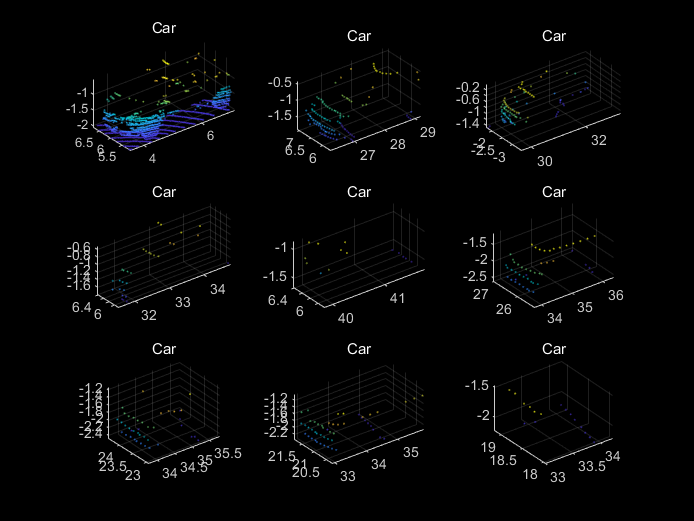

figure(2);
row = ceil(obsCount / 3);
[n,~] = size(point_cloud);
for k = 1:obsCount
    [max_x,~] = max(pos{k}(1,[1,2,5,6]));   
    [min_x,~] = min(pos{k}(1,[1,2,5,6])); 
    [max_y,~] = max(pos{k}(2,[1,2,5,6]));   
    [min_y,~] = min(pos{k}(2,[1,2,5,6]));
    point_selected = [];
    for i = 1:n
        if point_cloud(i,1)>min_x && point_cloud(i,1)<max_x...
           && point_cloud(i,2)>min_y && point_cloud(i,2)<max_y
            point_selected = [point_selected;point_cloud(i,:)];
        end
    end
    subplot(row,3,k);
    data = pointCloud([point_selected(:,1),point_selected(:,2),point_selected(:,3)]);
    pcshow(data);hold on;
    title(obsName{k});
end

## RANSAC算法去除地面点云

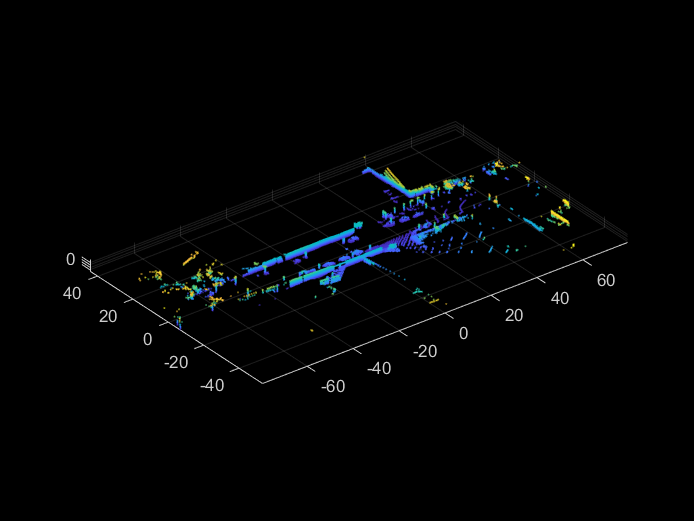


% options.epsilon = 1e-6;
% options.P_inlier = 0.90;
% options.sigma = 0.01;
% options.T_noise_squared = 0.002;
% options.est_fun = @estimate_plane;
% options.man_fun = @error_plane;
% options.mode = 'MSAC';
% options.Ps = [];
% options.notify_iters = [];
% options.min_iters = 1000;
% options.fix_seed = false;
% options.reestimate = true;
% options.stabilize = false;
% 
% processed_point_cloud = point_cloud((point_cloud(:,3)<-1)&(point_cloud(:,3)>-2.5),:);
% temp = 1:size(point_cloud,1);
% index = temp(point_cloud(:,3)<0);
% [results, options] = RANSAC(processed_point_cloud', options);
% ind = results.CS;
% plane_cloud_point = processed_point_cloud(ind,:);
% figure(3);
% data = pointCloud([plane_cloud_point(:,1),plane_cloud_point(:,2),plane_cloud_point(:,3)]);
% pcshow(data);hold on;
% title('The plane point cloud')
% 
% figure(4);
% temp1 = index(ind);
% temp2 = 1:size(point_cloud,1);
% temp2(temp1) = [];
% not_plane_cloud_point = point_cloud(temp2,:);
% data = pointCloud([not_plane_cloud_point(:,1),not_plane_cloud_point(:,2),not_plane_cloud_point(:,3)]);
% pcshow(data);hold on;
% title('The point cloud without plane')

% 手动去除地面？
figure(5);
processed_point_cloud = point_cloud(point_cloud(:,3)>-1.5,:);
data = pointCloud(processed_point_cloud(:,1:3));
pcshow(data);hold on;

## 栅格化

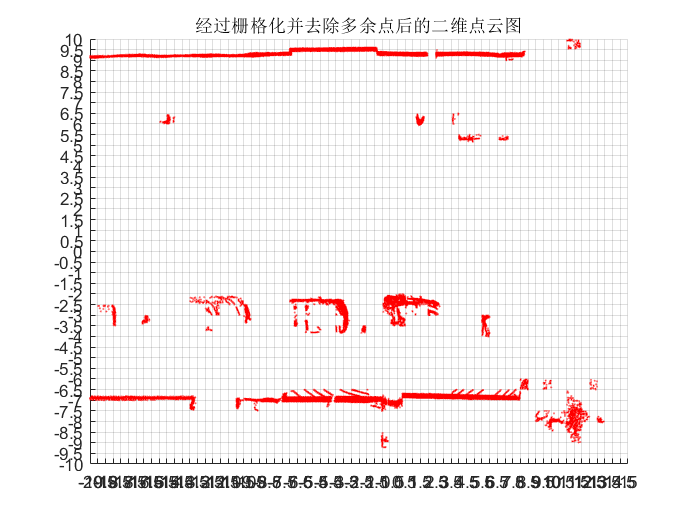

xmin = -20; xmax = 20; ymin = -10; ymax = 10;
d = 0.5;  % 1m*1m栅格尺寸 需要整除xmin and xmax and ymin and ymax
gridcell = cell((xmax-xmin)/d,(ymax-ymin)/d);  % 定义栅格存储cell
for i = 1:size(processed_point_cloud,1)
    point = processed_point_cloud(i,:);
    if point(1)>=xmax || point(1)<=xmin || point(2)>=ymax || point(2)<=ymin
        continue;
    end
    xgrid = ceil((point(1)-xmin)/d);    
    ygrid = ceil((point(2)-ymin)/d); 
    gridcell{xgrid,ygrid} = [gridcell{xgrid,ygrid};point];
end

% 判断有障碍物的栅格将其保留，其余删除
threshold_deltaZ = 0.3;
threshold_point_num = 10;
for i = 1:(xmax-xmin)/d
    for j = 1:(ymax-ymin)/d
        if isempty(gridcell{i,j})
            continue;
        end
        cell_point_count = size(gridcell{i,j},1);
        deltaZ = max(gridcell{i,j}(:,3))-min(gridcell{i,j}(:,3));
        if deltaZ < threshold_deltaZ || cell_point_count < threshold_point_num
            gridcell{i,j} = [];
        end
    end
end

figure(6);
for i = 1:(xmax-xmin)/d
    for j = 1:(ymax-ymin)/d
        if isempty(gridcell{i,j})
            continue;
        end
        scatter(gridcell{i,j}(:,1),gridcell{i,j}(:,2),1,'r.'); hold on;
    end
end
title('经过栅格化并去除多余点后的二维点云图')
set(gca,'XTick',xmin:d:xmax,'YTick',ymin:d:ymax);  % 绘制网格
grid on;

## DBSCAN栅格聚类

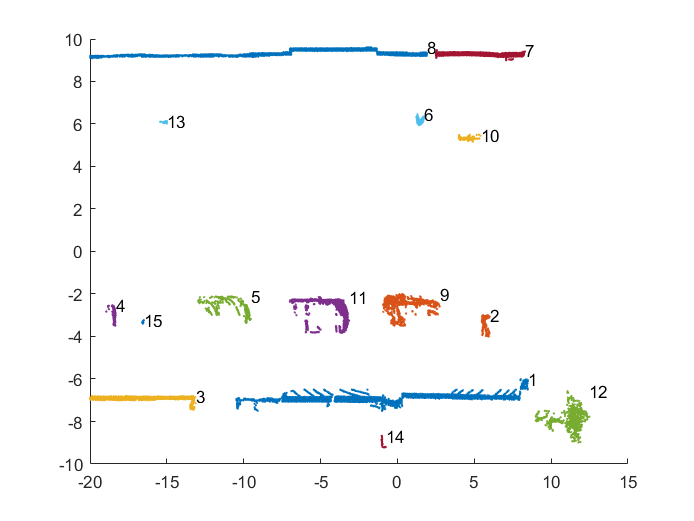

cellIndexNotEmpty = [];  % 保存非空的cell的(i,j)
ub = [(xmax-xmin)/d,(ymax-ymin)/d];
lb = [1,1];
for i = 1:ub(1)
    for j = 1:ub(2)
        if isempty(gridcell{i,j})
            continue;
        end
        cellIndexNotEmpty = [cellIndexNotEmpty;i,j 0]; %第三个分量表示栅格是否被访问
    end
end
C = {};  % 聚类类别的cell数组
MinPts = 45; % DBSCAN 参数，领域最小对象数
while any(cellIndexNotEmpty(:,3)==0)
    unvisited_grids = cellIndexNotEmpty(cellIndexNotEmpty(:,3)==0,:);
    random_index = randperm(size(unvisited_grids,1),1);
    p = unvisited_grids(random_index,1:2);
    cellIndexNotEmpty(cellIndexNotEmpty(:,1)==p(1)&cellIndexNotEmpty(:,2)==p(2),3) = 1;  % 标记被访问
    
    neighborhood = [p(1)+1,p(2);p(1)-1,p(2);p(1),p(2)-1;p(1),p(2)+1;...
                    p(1)-1,p(2)-1;p(1)-1,p(2)+1;p(1)+1,p(2)-1;p(1)+1,p(2)+1];
                
    point_num = 0;
    delete_index = [];
    for i = 1:size(neighborhood,1) 
        flag_ub = neighborhood(i,:)>ub;
        flag_lb = neighborhood(i,:)<lb;
        if any(flag_lb+flag_ub)
            delete_index = [delete_index,i];
            continue;
        end
        if isempty(gridcell{neighborhood(i,1),neighborhood(i,2)})
            delete_index = [delete_index,i];
            continue;
        end
        neighbor = neighborhood(i,:);
        point_num = point_num + size(gridcell{neighbor(1),neighbor(2)},1);
    end
    neighborhood(delete_index,:) = [];
    
    if point_num >= MinPts
        if isempty(C)
            C = {p};
        else
            C{end+1} = p;
        end
        while ~isempty(neighborhood)
            neighbor = neighborhood(1,:);
            neighborhood(1,:) = [];
            if cellIndexNotEmpty(cellIndexNotEmpty(:,1)==neighbor(1)&...
               cellIndexNotEmpty(:,2)==neighbor(2),3) == 0
                cellIndexNotEmpty(cellIndexNotEmpty(:,1)==neighbor(1)&...
               cellIndexNotEmpty(:,2)==neighbor(2),3) = 1; % 标记被访问
                neighborhood_ =  [neighbor(1)+1,neighbor(2);neighbor(1)-1,neighbor(2);...
                                 neighbor(1),neighbor(2)-1;neighbor(1),neighbor(2)+1;...
                                 neighbor(1)-1,neighbor(2)-1;neighbor(1)-1,neighbor(2)+1;...
                                 neighbor(1)+1,neighbor(2)-1;neighbor(1)+1,neighbor(2)+1];
                point_num = 0;
                delete_index = [];
                for k = 1:size(neighborhood_,1)
                   flag_ub = neighborhood_(k,:)>ub;
                   flag_lb = neighborhood_(k,:)<lb;
                   if any(flag_lb+flag_ub)
                       delete_index = [delete_index,k];
                       continue;
                   end
                   if isempty(gridcell{neighborhood_(k,1),neighborhood_(k,2)})
                      delete_index = [delete_index,k];
                      continue;
                   end
                   neighbor_ = neighborhood_(k,:);
                   point_num = point_num + size(gridcell{neighbor_(1),neighbor_(2)},1);
                end
                neighborhood_(delete_index,:) = [];
                
                if point_num >= MinPts
                    neighborhood = [neighborhood;neighborhood_];
                    flag = false;
                    for m = 1:size(C,2)
                        temp = C{m};
                        if any(temp(:,1)==neighbor(1)&temp(:,2)==neighbor(2))
                            flag = true;
                            break;
                        end
                    end
                    if ~flag
                        C{end} = [C{end};neighbor];
                    end
                end
            end
        end
    end
end
cluster = {};  % 存放不同类别点云坐标    
figure(7);
for i = 1:size(C,2)
    temp = C{i};
    t2 = [];
    for j = 1:size(temp,1)
        t = temp(j,:);
        x_lb = (t(1)-1)*d+xmin; x_ub = t(1)*d+xmin;
        y_lb = (t(2)-1)*d+ymin; y_ub = t(2)*d+ymin;
        t1 = point_cloud(:,1)>=x_lb & point_cloud(:,1)<=x_ub...
             & point_cloud(:,2)>=y_lb & point_cloud(:,2)<=y_ub...
             & point_cloud(:,3)>-1.5;
        t2 = [t2;point_cloud(t1,:)];
    end
    if isempty(cluster)
        cluster = {t2};
    else
        cluster{end+1} = t2;
    end
    scatter(t2(:,1),t2(:,2),1); hold on;
    text(max(t2(:,1)),max(t2(:,2)),num2str(i))
end

cluster  % 显示本节代码结果（聚类结果）

cluster = 1×15 cell 数组
    {18576×4 double}    {916×4 double}    {1144×4 double}    {119×4 double}    {328×4 double}    {906×4 double}    {4781×4 double}    {13882×4 double}    {5244×4 double}    {132×4 double}    {2491×4 double}    {821×4 double}    {42×4 double}    {29×4 double}    {10×4 double}


## 获取训练点云数据

% files = dir("./training/velodyne/*.bin");
% car_point = {};           % 存储car障碍点云元胞
% pedestrian_point = {};     % 存储pedestrain障碍点云元胞
% cyclist_point = {};      % 存储cyclist障碍点云元胞
% misc_point = {};          % 存储杂项障碍点云元胞
% load_file_num = 2000;       % 读取的点云文件数
% for k = 1:load_file_num
%     filename = files(k).name;
%     fid=fopen(['./training/velodyne/',filename],'rb');
%     [a,count]=fread(fid,'float32');
%     fclose(fid);
%     x = a(1:4:end);
%     y = a(2:4:end);
%     z = a(3:4:end);
%     reflectivity = a(4:4:end);  % 反射率
%     point_cloud = [x,y,z,reflectivity];
%     label = importdata(['./training/label/',filename(1:6),'.txt']);
%     data_label = label.data;
%     obsName = label.textdata;
%     data_calib = importdata(['./training/calib/',filename(1:6),'.txt']);
%     Tr_velo_to_cam = reshape(data_calib.data(end-1,:),[4,3])';
%     Tr_velo_to_cam = [Tr_velo_to_cam;0 0 0 1];
%     pos = {};                 % 创建一个cell数组用于存储障碍物坐标
%     obsNum = size(obsName,1); % 包含DontCare类障碍物的总个数
%     for i = 1:obsNum
%         if obsName{i} == "DontCare"
%             continue;
%         end
%         la = data_label(i,:);
%         obsPos = la(11:13)';
%         [h,w,l] = deal(la(8),la(9),la(10));
%         r_y = la(end);
%         % t1~t8为障碍物坐标系下的坐标（不考虑障碍物旋转，默认长边与x-axis平行）
%         t1 = [l/2,0,w/2];
%         t2 = [l/2,0,-w/2];
%         t3 = [l/2,-h,w/2];
%         t4 = [l/2,-h,-w/2];
%         t5 = [-l/2,0,w/2];
%         t6 = [-l/2,0,-w/2];
%         t7 = [-l/2,-h,w/2];
%         t8 = [-l/2,-h,-w/2];
%         % 考虑障碍物旋转角度r_y，对x,z方向进行更新
%         T = [t1;t2;t3;t4;t5;t6;t7;t8];
%         R = [cos(r_y),-sin(r_y);sin(r_y),cos(r_y)];
%         T(:,[1,3]) = (R*T(:,[1,3])')';
%         % 考虑障碍物坐标系与相机坐标系坐标位移
%         T(:,1) = T(:,1) + obsPos(1);
%         T(:,2) = T(:,2) + obsPos(2);
%         T(:,3) = T(:,3) + obsPos(3);
%         % 将相机坐标系转化到激光雷达坐标系
%         velo_pos = Tr_velo_to_cam\[T';1,1,1,1,1,1,1,1];
%         velo_pos = velo_pos(1:3,:);
%         % 记录障碍Box坐标
%         pos{i} = velo_pos;
%     end
% 
%     [n,~] = size(point_cloud);
%     
%     for i = 1:obsNum
%         if obsName{i} == "DontCare"
%             continue;
%         end
%         [max_x,~] = max(pos{i}(1,[1,2,5,6]));   
%         [min_x,~] = min(pos{i}(1,[1,2,5,6])); 
%         [max_y,~] = max(pos{i}(2,[1,2,5,6]));   
%         [min_y,~] = min(pos{i}(2,[1,2,5,6]));
%         la = data_label(i,:);
%         [h,w,l] = deal(la(8),la(9),la(10));
%         point_selected = [];
%         for j = 1:n
%             if point_cloud(j,1)>min_x && point_cloud(j,1)<max_x...
%                && point_cloud(j,2)>min_y && point_cloud(j,2)<max_y && point_cloud(j,3)>-1.5
%                 point_selected = [point_selected;point_cloud(j,:)];
%             end
%         end
%         point_selected = [l,w,h,0;point_selected];   % 数据集第一行数据为[l w h 0],0只是占位
%         if obsName{i} == "Car" && size(point_selected,1)>200
%             if isempty(car_point)
%                 car_point = {point_selected};
%             else
%                 car_point{end+1} = point_selected;
%             end
%         end
%         if obsName{i} == "Pedestrian" && size(point_selected,1)>100
%             if isempty(pedestrian_point)
%                 pedestrian_point = {point_selected};
%             else
%                 pedestrian_point{end+1} = point_selected;
%             end
%         end
%         if obsName{i} == "Cyclist" && size(point_selected,1)>100
%             if isempty(cyclist_point)
%                 cyclist_point = {point_selected};
%             else
%                 cyclist_point{end+1} = point_selected;
%             end
%         end
%         if obsName{i} == "Misc" && size(point_selected,1)>40
%            if isempty(misc_point)
%                misc_point = {point_selected};
%            else
%                misc_point{end+1} = point_selected;
%            end
%        end
%     end
% end

% figure(8);
% pcshow(pointCloud(misc_point{3}(2:end,1:3)))

% for i = 1:size(car_point,2)
%     writematrix(car_point{i},['./training/car/',num2str(i),'.csv']);   
% end
% for i = 1:size(pedestrian_point,2)
%     writematrix(pedestrian_point{i},['./training/pedestrian/',num2str(i),'.csv']);
% end
% for i = 1:size(cyclist_point,2)
%     writematrix(cyclist_point{i},['./training/cyclist/',num2str(i),'.csv']);
% end
% for i = 1:size(misc_point,2)
%     writematrix(misc_point{i},['./training/misc/',num2str(i),'.csv']);
% end

## 测试神经网络分类器（保存聚类结果csv供Python测试）

% cluster点云存储
% for i = 1:size(cluster,2)
%     temp = cluster{i};
%     max_x = max(temp(:,1));
%     min_x = min(temp(:,1));
%     max_y = max(temp(:,2));
%     min_y = min(temp(:,2));
%     h = max(temp(:,3)) - min(temp(:,3));
%     if max_x - min_x > max_y - min_y
%         l = max_x - min_x;
%         w = max_y - min_y;
%     else
%         l = max_y - min_y;
%         w = max_x - min_x;
%     end
%     writematrix([l,w,h,0;temp],['./testing/cluster/',num2str(i),'.csv']); 
% end

## 加载Python得到的模型参数手写前向传播

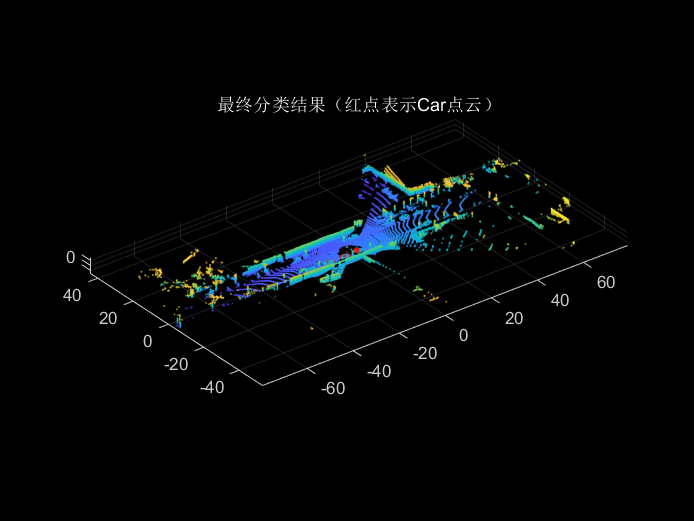

load('para_save_open.mat');
figure(9);
data = pointCloud(point_cloud(:,1:3));
pcshow(data);hold on;
figure(10);
for i = 1:size(cluster,2)
    temp = cluster{i};
    max_x = max(temp(:,1));
    min_x = min(temp(:,1));
    max_y = max(temp(:,2));
    min_y = min(temp(:,2));
    h = max(temp(:,3)) - min(temp(:,3));
    if max_x - min_x > max_y - min_y
        l = max_x - min_x;
        w = max_y - min_y;
    else
        l = max_y - min_y;
        w = max_x - min_x;
    end
    f = feature_extract([l,w,h,0;temp]);
    res = policy_net_sign_bankangle(f');
    [~,index] = max(res,[],1);
    if index == 1
        figure(9);
        scatter3(temp(:,1),temp(:,2),temp(:,3),1,'r.');
        figure(10);
        bar1 = scatter(temp(:,1),temp(:,2),1,'r.'); hold on;
    elseif index == 2
        figure(10);
        bar2 = scatter(temp(:,1),temp(:,2),1,'b.');hold on;
    end
end
figure(9);
title("最终分类结果（红点表示Car点云）")

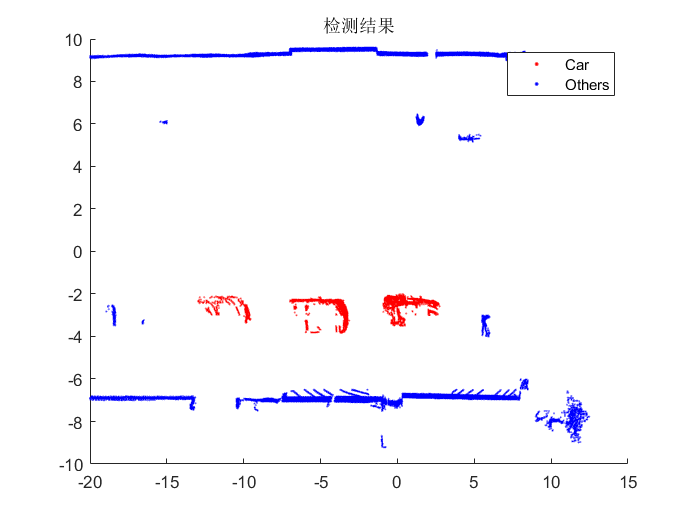

figure(10);
legend([bar1,bar2],["Car","Others"]);
title('检测结果')

## 查看RGB图

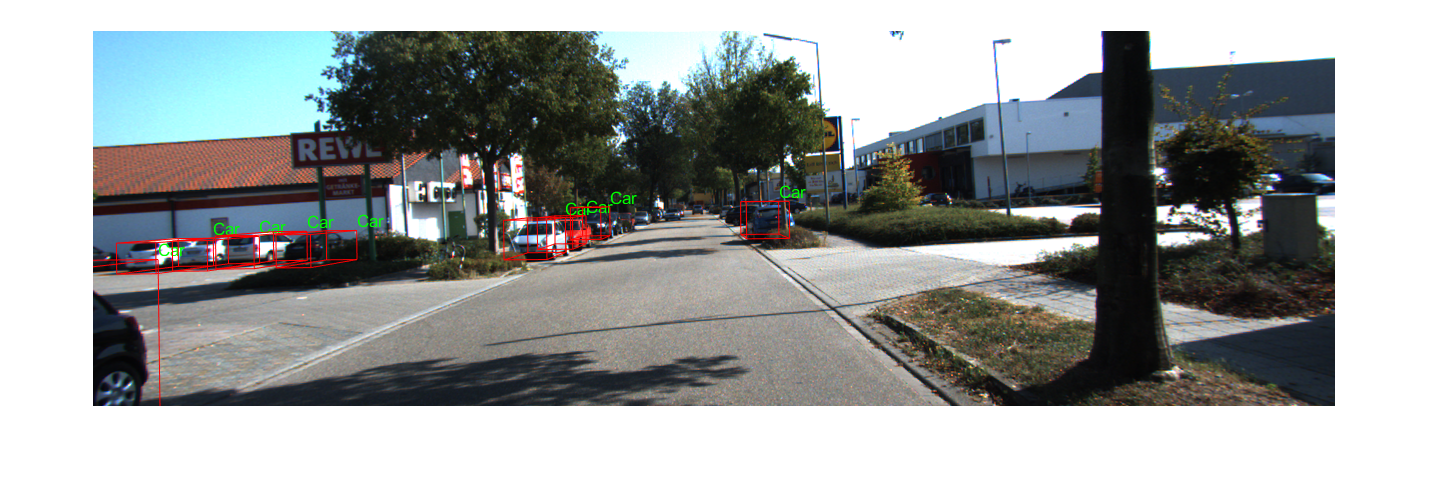

figure()
Image = imread(['./training/image_2/',file,'.png']);
imshow(Image); hold on;
P2 = reshape(data_calib.data(3,:),[4,3])';
R0_rect = reshape(data_calib.data(5,1:end-3),[3,3])';
R0_rect = [R0_rect,[0;0;0];[0,0,0,1]];
for i = 1:obsNum
    if obsName{i} == "DontCare"
        continue;
    end
    la = data_label(i,:);
    obsPos = la(11:13)';
    [h,w,l] = deal(la(8),la(9),la(10));
    r_y = la(end);
    % t1~t8为障碍物坐标系下的坐标（不考虑障碍物旋转，默认长边与x-axis平行）
    t1 = [l/2,0,w/2];
    t2 = [l/2,0,-w/2];
    t3 = [l/2,-h,w/2];
    t4 = [l/2,-h,-w/2];
    t5 = [-l/2,0,w/2];
    t6 = [-l/2,0,-w/2];
    t7 = [-l/2,-h,w/2];
    t8 = [-l/2,-h,-w/2];
    % 考虑障碍物旋转角度r_y，对x,z方向进行更新
    T = [t1;t2;t3;t4;t5;t6;t7;t8];
    R = [cos(r_y),-sin(r_y);sin(r_y),cos(r_y)];
    T(:,[1,3]) = (R*T(:,[1,3])')';
    % 考虑障碍物坐标系与相机坐标系坐标位移
    T(:,1) = T(:,1) + obsPos(1);
    T(:,2) = T(:,2) + obsPos(2);
    T(:,3) = T(:,3) + obsPos(3);
    T = [T';1,1,1,1,1,1,1,1];
    res = P2*R0_rect*T;   % 从参考相机坐标系到左彩色相机图像坐标
    for j = 1:size(res,2)
        res(:,j) = res(:,j)/res(3,j);
    end
    res = res(1:2,:);
    % 绘制12根线构成3D-Box
    temp = res(:,[3,4,8,7]);
    [~,j] = min(res(2,[3,4,8,7]));
    textPoint = temp(:,j);
    text(textPoint(1),textPoint(2)-10,obsName{i},'Color','green');
    plot(res(1,[1,2,6,5,1]),res(2,[1,2,6,5,1]),'Color','r');
    plot(res(1,[3,4,8,7,3]),res(2,[3,4,8,7,3]),'Color','r');
    plot(res(1,[1,3]),res(2,[1,3]),'Color','r');
    plot(res(1,[2,4]),res(2,[2,4]),'Color','r');
    plot(res(1,[6,8]),res(2,[6,8]),'Color','r');
    plot(res(1,[5,7]),res(2,[5,7]),'Color','r');
end

特征提取函数，需要和Python训练时函数一致

function f = feature_extract(data)
point_cloud = data(2:end,1:3);
ref = data(2:end,4);
h = data(1,3);
w = data(1,2);
max_x = max(point_cloud(:,1));
min_x = min(point_cloud(:,1));
max_y = max(point_cloud(:,2));
min_y = min(point_cloud(:,2));
f1 = [w,h];
slices_num = 10;
if max_x - min_x > max_y - min_y
    t = linspace(min_x,max_x,slices_num+1);
    flag = 1;
else
    t = linspace(min_y,max_y,slices_num+1);
    flag = 2;
end
f2 = [];
for i = 1:size(t,2)-1
    lb = t(i); ub = t(i+1);
    sum_h = 0; num = 0;
    for j = 1:size(point_cloud,1)
        point = point_cloud(j,:);
        if point(flag)<ub && point(flag)>lb
            sum_h = sum_h + point(3);
            num = num + 1;
        end
    end
    if num == 0
        f2 = [f2,0];
    else
        f2 = [f2,sum_h/num];
    end
end
if flag == 1
    f3 = (max_y-min_y)/h;
else
    f3 = (max_x-min_x)/h;
end
f4 = [mean(ref),std(ref)];
num1 = 0; num2 = 0;
for i = 1:size(ref)
    if ref(i)>=0 && ref(i)<0.2
        num1 = num1 + 1;
    end
    if ref(i)>=0.2 && ref(i)<0.4
        num2 = num2 + 1;
    end
end
f5 = (num1-num2)/size(point_cloud,1);
f = [f1,f2,f3,f4,f5];
end